% 方程 -Uxx-Uyy=4 边界值在圆上是0
f=@(x,y)4

f = function_handle with value:
    @(x,y)4


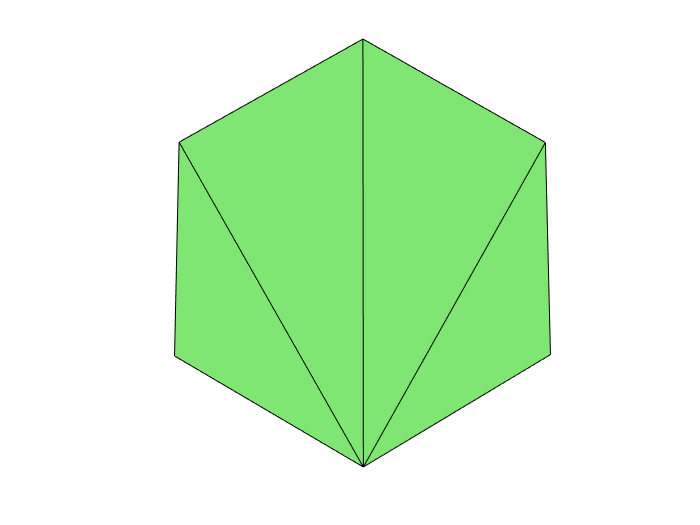

ans =   Patch with properties:

    FaceColor: [0.5000 0.9000 0.4500]
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [4×3 double]
     Vertices: [6×3 double]

  Show all properties


 - Min quality 0.47
 - Mean quality 0.60
 - Uniformity 0.0%
 



% 生成网格 利用 distmesh2d 自动生成
fd=@(p) sqrt(sum(p.^2,2))-1; % 距离函数 确定所需要的区域
[p,t]=distmesh2d(fd,@huniform,0.5,[-1,-1;1,1],[]); % p 每个顶点的坐标 t(N*3) N个三角形对应的顶点标号

b=unique(boundedges(p,t)); % 边界对应的顶点们的序号

% 计算K F
N=size(p,1); % 节点数
T=size(t,1); % 三角形数
K=sparse(N,N); % 初始化为全零稀疏矩阵
F=zeros(N,1); % 全零

% 对每个三角形元计算 Fe Ke
for e=1:T
    nodes=t(e,:); % 所取三角形的三个节点序号
    Pe=[ones(3,1),p(nodes,:)]; % 2S=|Pe| 得到S的行列式
    S=abs(det(Pe))/2; % 求出 S 面积
    C=inv(Pe); % 求 a+bx+cy 中的系数 a b c 的时候有求逆
    
    % 计算 Ke 和 Fe
    grad=C(2:3,:); % B
    Ke=S*grad'*grad; % 计算 Ke
    Fe=S/3*4; % 这里刚好 f 是定值4
    
    % 更新到总刚度矩阵 K 和总荷载量 F
    K(nodes,nodes)=K(nodes,nodes)+Ke; 
    F(nodes)=F(nodes)+Fe;
end

K1 = full(K)

K1 =     1.7060   -0.8666         0   -0.8394         0         0
   -0.8666    1.7503   -0.8837   -0.0000         0         0
         0   -0.8837    1.7728   -0.0000   -0.8891         0
   -0.8394   -0.0000   -0.0000    1.6826   -0.0000   -0.8433
         0         0   -0.8891   -0.0000    1.7651   -0.8760
         0         0         0   -0.8433   -0.8760    1.7193


F1 = F

F1 =     0.5951
    1.7411
    2.2822
    3.4635
    1.7224
    0.5861


U1 = K\F

U1 = 	1.0e+16 *

    2.2840
    2.2840
    2.2840
    2.2840
    2.2840
    2.2840



% 添加边界条件
K(b,:)=0; K(:,b)=0; F(b)=0; % 将边界处的 K 和 F 设置为边界条件需要的0
K(b,b)=speye(length(b),length(b)); % 将 K 中的其他位置补充1

% 求解 U
full(K)

ans =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


F

F =      0
     0
     0
     0
     0
     0


U = K\F

U =      0
     0
     0
     0
     0
     0


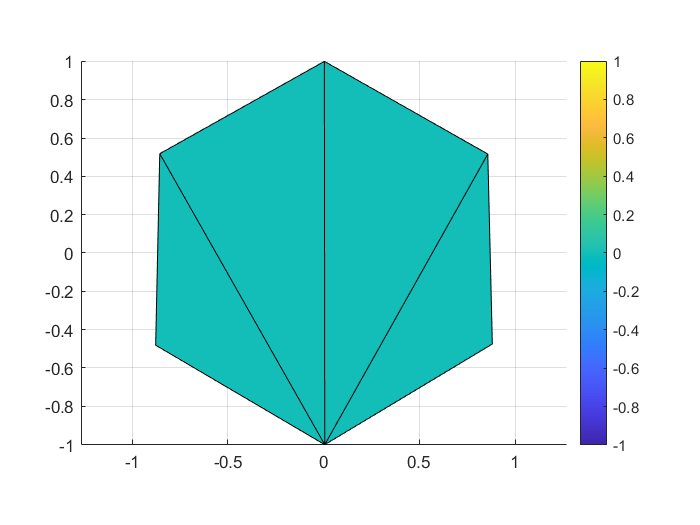


% 有限元得到结果
trisurf(t,p(:,1),p(:,2),0*p(:,1),U,'edgecolor','k','facecolor','interp');
view(2),axis([-1 1 -1 1]),axis equal,colorbar

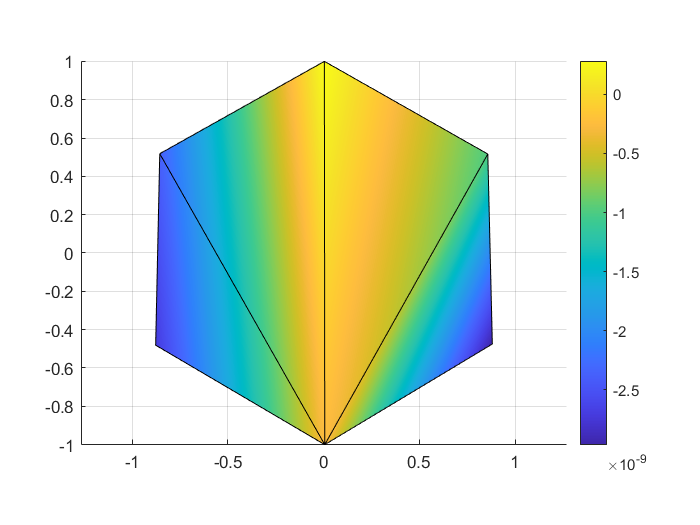


% 真实结果
u = 1 - p(:,1).^2 - p(:,2).^2;
trisurf(t,p(:,1),p(:,2),0*p(:,1),u,'edgecolor','k','facecolor','interp');
view(2),axis([-1 1 -1 1]),axis equal,colorbar

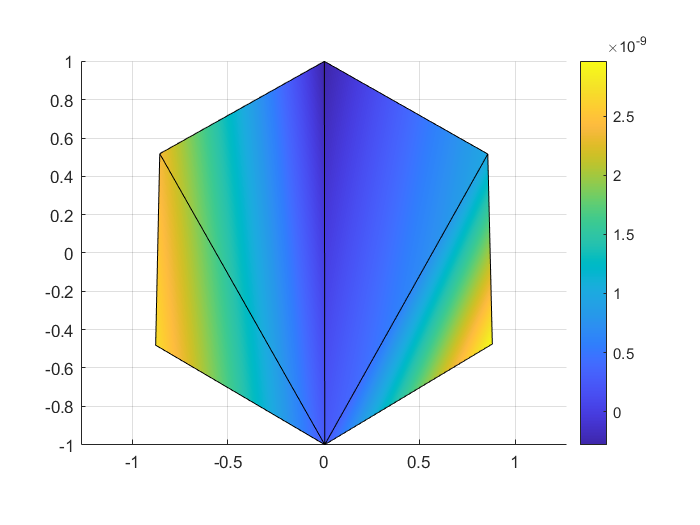


% 误差
trisurf(t,p(:,1),p(:,2),0*p(:,1),U-u,'edgecolor','k','facecolor','interp');
view(2),axis([-1 1 -1 1]),axis equal,colorbar